# 线性规划linprog求解

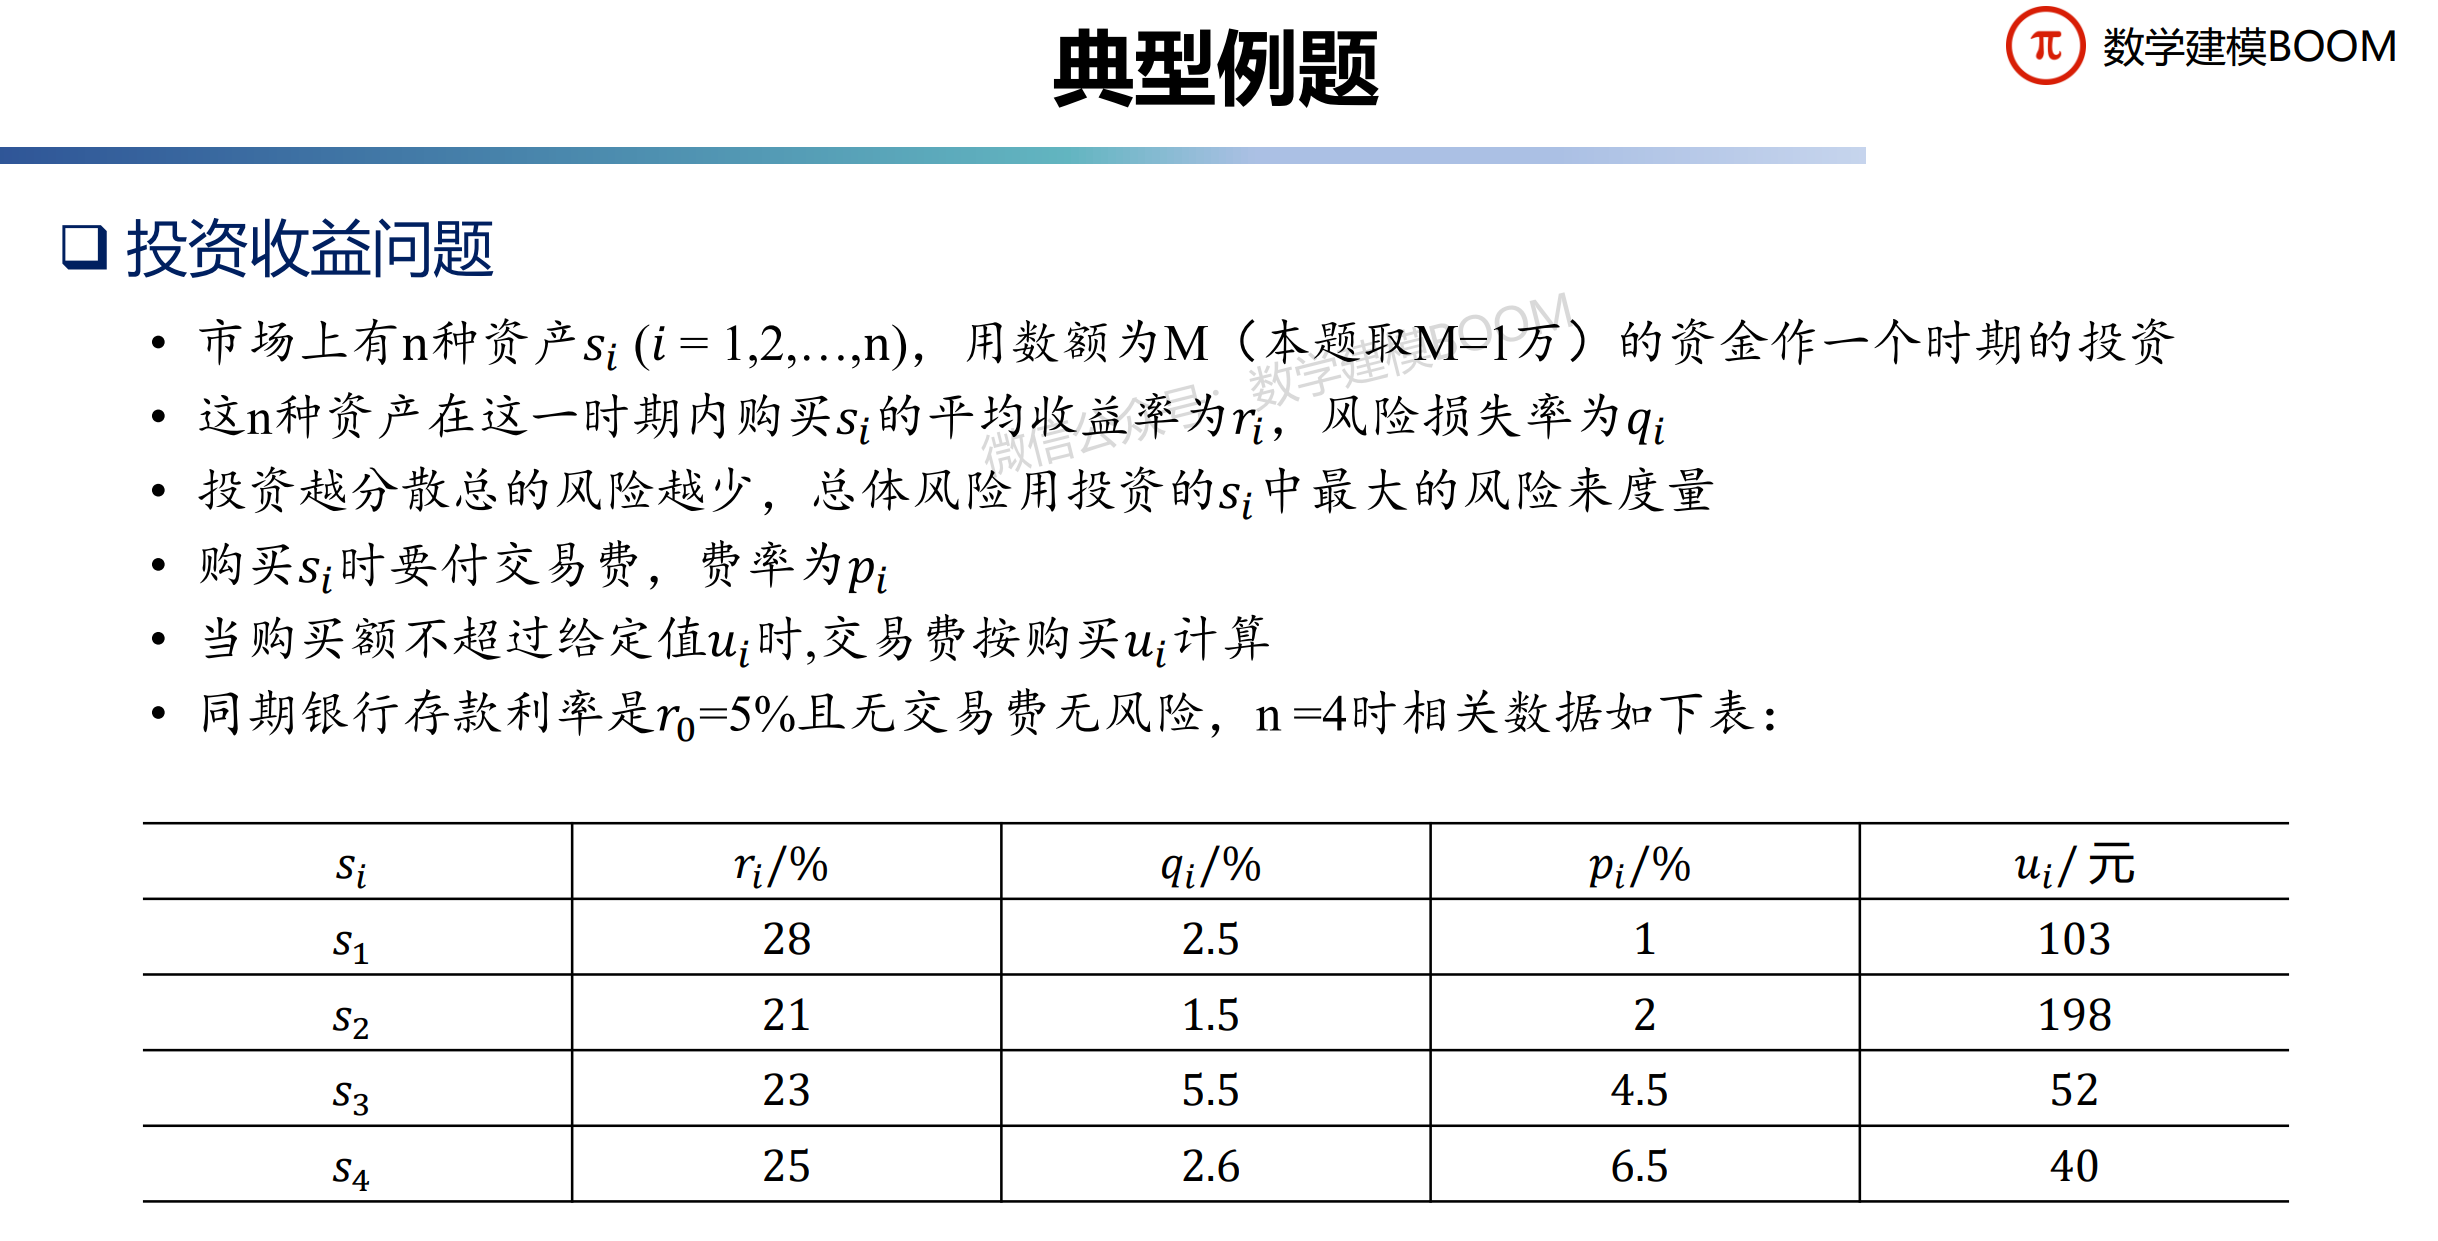

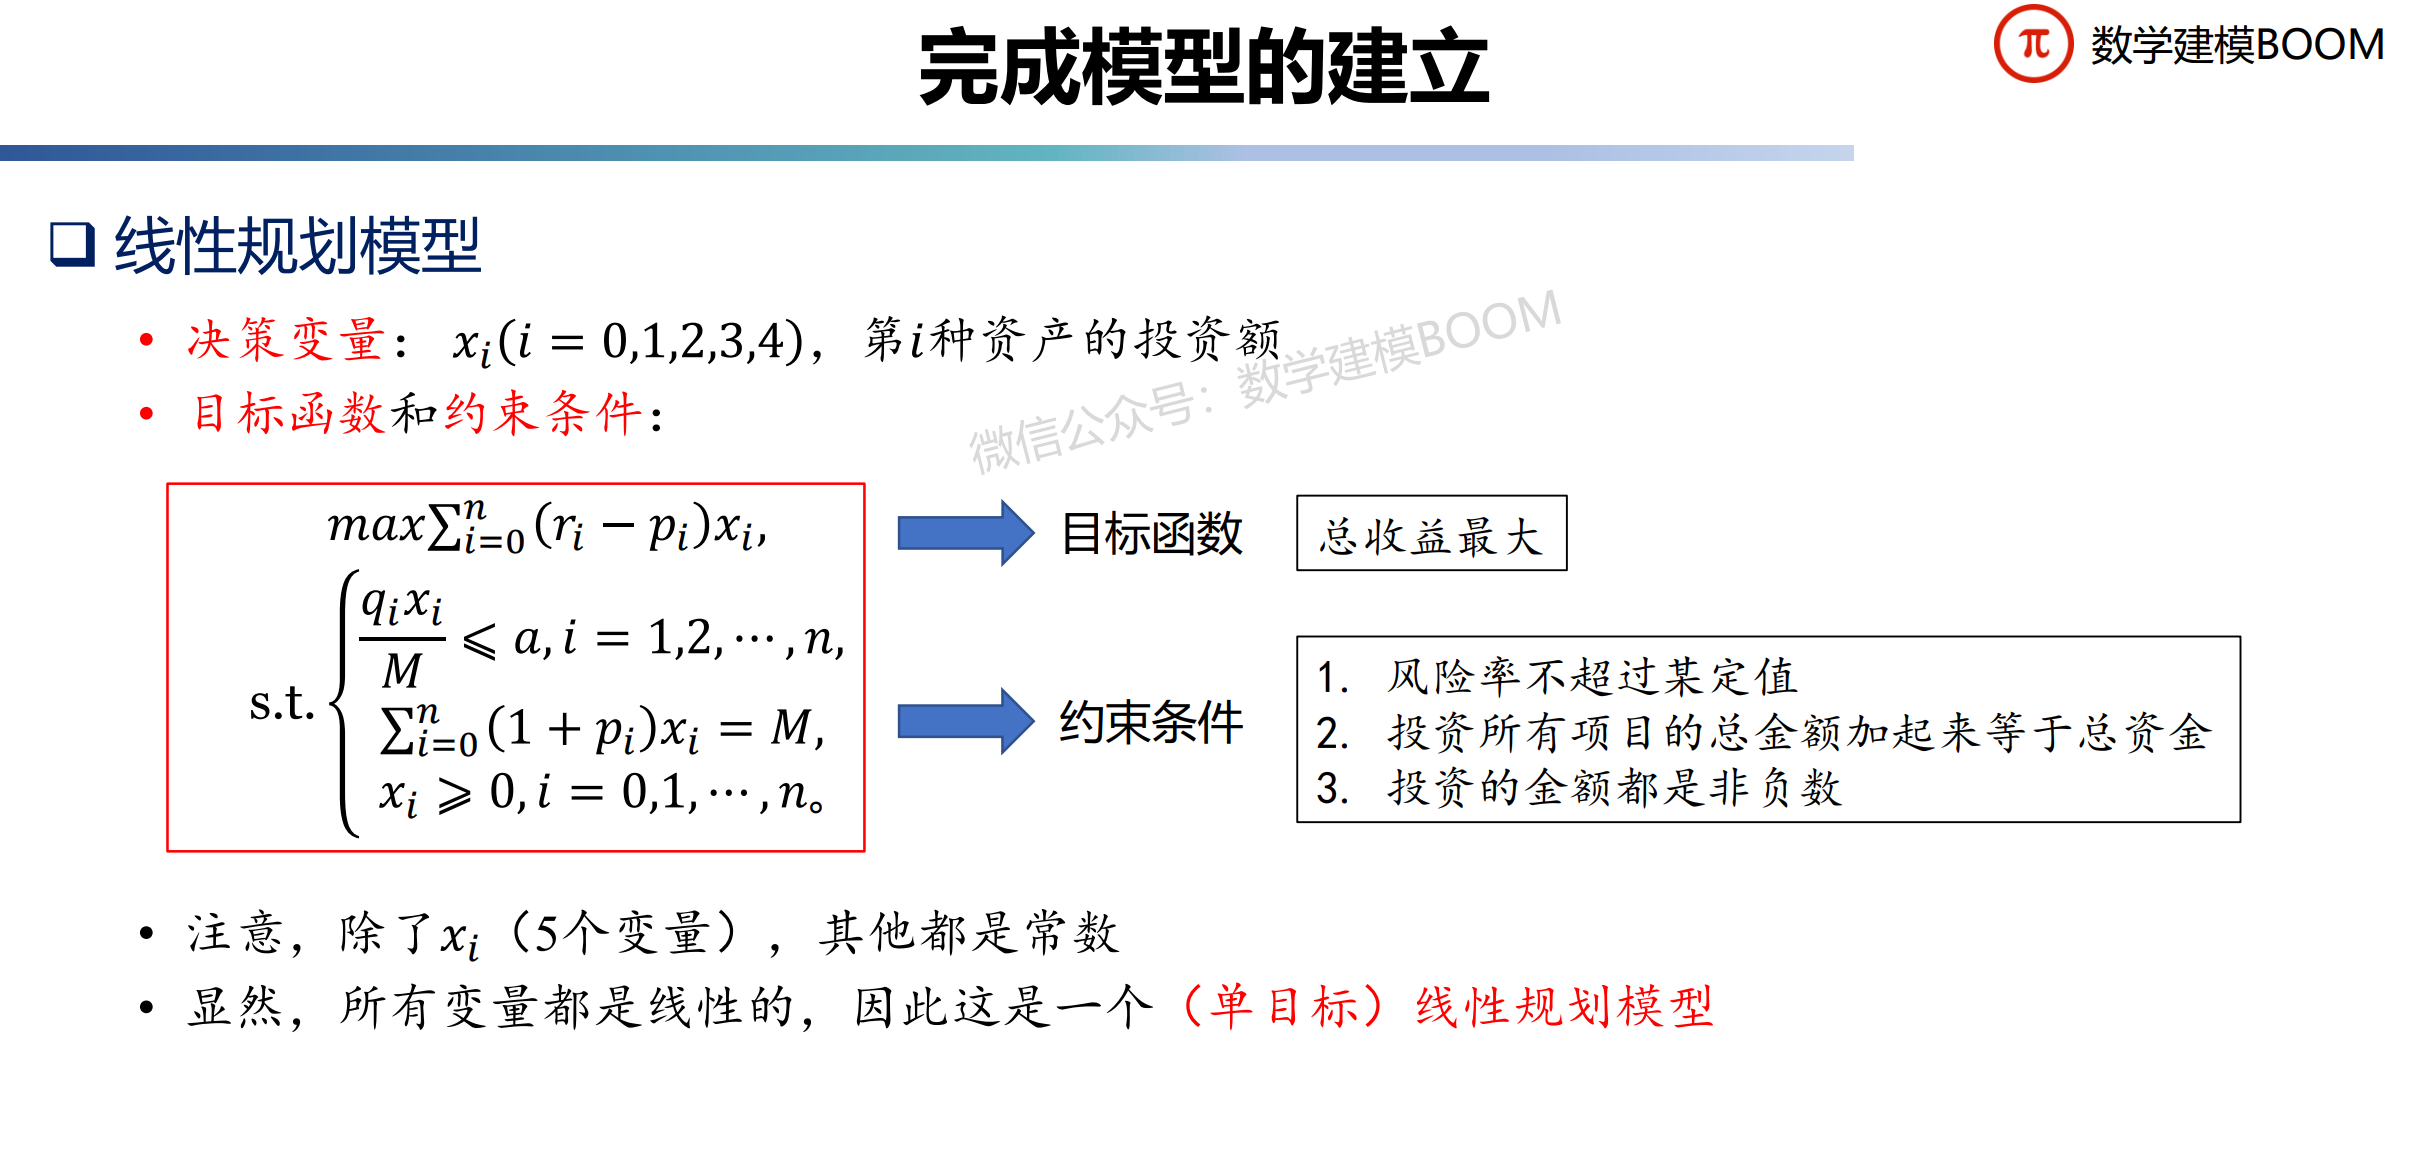

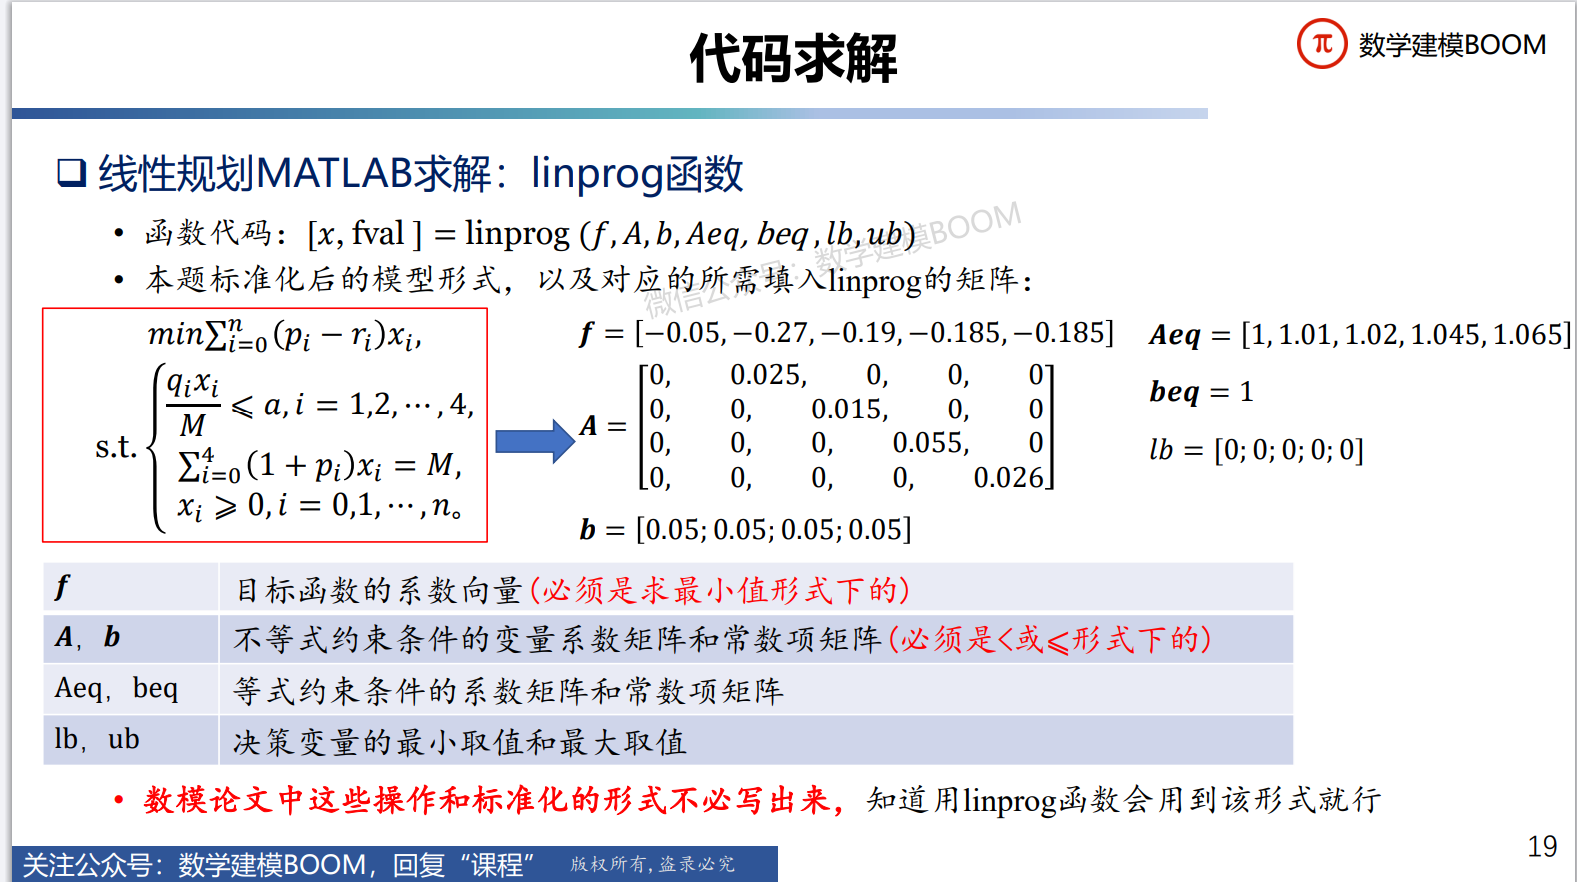

a = (0:0.001:0.05);
f = [-0.05, -0.27, -0.19, -0.185, -0.285];
A = [zeros(4,1),diag([0.025, 0.015, 0.055, 0.026])];
Aeq = [1, 1.01, 1.02, 1.045, 1.065];
beq = 1;
LB = zeros(5,1);
Q = zeros(1, length(a));
XX = [];

for i = 1:length(a)
    b = a(i)*ones(4,1);
    [x,y] = linprog(f, A, b, Aeq, beq, LB);
    Q(i) = -y;
    XX = [XX; x'];
end

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solu

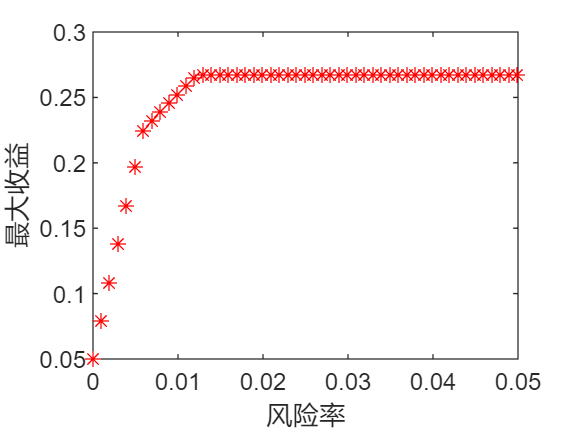


plot(a,Q,'*r');
xlabel('风险率');
ylabel('最大收益');